# 文本数据绘图

## 初始化

close all;
clear;
clc;

## 导入数据

### **一**

D = readtable('/Users/WangHao/Desktop/train.txt', ...
    'Delimiter', ':', 'ReadVariableNames', false);
A = table2array(D);

### **二**

D = readtable('/Users/WangHao/Desktop/test_loss_accuracy.txt', ...
    'Delimiter', {':', ';'}, 'ReadVariableNames', false);
A = table2array(D);

## 极值位置

[r, c] = find(A == min(A(:, 2)));
Epoch = A(r, c-1);
Result = min(A(:, 2));
disp([Epoch Result]);

## 建立图窗

figure('Name', 'Example');

## 绘制曲线

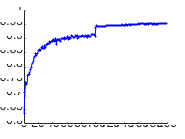

hold on
plot(A(:, 1), A(:, 3),...
     '-o',...  % 线型，点型，线色，线宽，点尺寸，点边缘色，点填充色
     'LineWidth', 1.5,...
     'color', 'b',...
     'MarkerSize', 5,...
     'MarkerEdgeColor', 'b',...
     'MarkerFaceColor', 'b'...
     );

 
% hold off

## 信息标注

### **一**

x1 = 0;
x2 = max(A(:, 1));

### **二**

#### **正**

y1 = 0;  
y2 = 1.025*round(max(A(:, 2)), 2);

y1 = 0;
y2 = 1;

#### **负**

y1 = 1.025*round(min(A(:, 2)), 2);
y2 = 0;

y1 = -1;
y2 = 0;

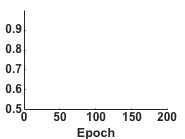

axis([0 200 0.5 1])
set(gca, 'linewidth', 1.5)
% set(gca, 'xtick', x1 : 20 : x2, ...
%     'ytick', y1 : round((y2-y1)/10, 2) : y2);
set(gca, 'FontName', 'Arial', 'FontSize', 28, 'FontWeight', 'bold');
xlabel('Epoch', 'FontName', 'Arial', 'FontSize', 38, 'FontWeight', 'bold'); 

### 三

#### **正**

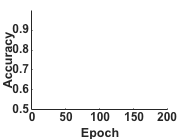

ylabel('Accuracy', 'FontName', 'Arial', 'FontSize', 38, 'FontWeight', 'bold'); 

% title('Train', 'FontName', 'Times New Roman', 'FontSize', 32, 'FontWeight', 'bold');

#### **负**

ylabel('Loss', 'FontName', 'Arial', 'FontSize', 38, 'FontWeight', 'bold'); 

% title('Test', 'FontName', 'Times New Roman', 'FontSize', 32, 'FontWeight', 'bold');

### 四

text(A(1, 1)+1, A(1, 2), strcat('(', num2str(A(1, 1)),',', sprintf('%.4f', A(1, 2)), ')'),... 
     'FontName', 'Times New Roman', 'FontSize', 16, 'FontWeight', 'bold'...
     );
 
text(A(end, 1)+1, A(end, 2), strcat('(', num2str(A(end,1)),',', sprintf('%.4f', A(end, 2)), ')'),... 
     'FontName', 'Times New Roman', 'FontSize', 16, 'FontWeight', 'bold'...
     );
 
text(Epoch, Result+0.025*(y2-y1), strcat('(', num2str(Epoch),',', sprintf('%.4f', Result), ')'),... 
     'FontName', 'Times New Roman', 'FontSize', 16, 'FontWeight', 'bold'...
     ); 

scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);

### 五

legend({'BatchSize 1', 'BatchSize 2', 'BatchSize 3', 'BatchSize 4', 'BatchSize 5'}, 'FontName', 'Times New Roman', 'FontSize', 24)
legend({'Learning Rate 1e-4', 'Learning Rate 1e-5', 'Learning Rate 1e-6', 'Learning Rate 4', 'Learning Rate 5'}, 'FontName', 'Times New Roman', 'FontSize', 24)

## 导出图窗

### 一

box off;
% 完全去除间隔, 可能会去除掉边界的一些信息, 请检查后使用
set(gca,'LooseInset', get(gca,'TightInset'))
% set(gca, 'xgrid', 'on'); 
set(gca, 'ygrid', 'on'); 
% set(gca, 'xminorgrid', 'on'); 
set(gca, 'yminorgrid', 'on'); 

### 二

print(gcf, 'D:\桌面\Train', '-dpng', '-r300');
print(gcf, 'D:\桌面\Train', '-dsvg');

### 三

print(gcf, 'D:\桌面\Test', '-dpng', '-r300');
print(gcf, 'D:\桌面\Test', '-dsvg');